# WASABI Connectivity Demo

% Display helper functions: Called by later scripts
% --------------------------------------------------------

dashes = '--------------------------------------------------------------------------------------------';
printstr = @(dashes) disp(dashes);
printhdr = @(str) fprintf('%s\n%s\n%s\n', dashes, str, dashes);

printhdr(' ')

--------------------------------------------------------------------------------------------
 
--------------------------------------------------------------------------------------------


printhdr('This walkthrough uses CANlab tools to look at connectivity for one participant')

--------------------------------------------------------------------------------------------
This walkthrough uses CANlab tools to look at connectivity for one participant
--------------------------------------------------------------------------------------------


printhdr(' ')

--------------------------------------------------------------------------------------------
 
--------------------------------------------------------------------------------------------


## Get data image names (list files)

create a cell array, imgs, with one cell per subject this contains the file names for the BOLD images for each subject

datadir='\\dartfs-hpc\rc\lab\C\CANlab\labdata\data\WASABI\derivatives\fmriprep';
subj = canlab_list_subjects(datadir, 'sub-*');

imgs = canlab_list_files(datadir, subj, '*preproc_bold.nii.gz');

f

f =   fmri_data with properties:

          source_notes: 'Info about image source here'
                     X: []
                  mask: [1×1 fmri_mask_image]
          mask_descrip: ' CHANGED SPACE'
    images_per_session: []
                     Y: []
               Y_names: []
             Y_descrip: 'Behavioral or outcome data matrix.'
            covariates: []
       covariate_names: {''}
    covariates_descrip: 'Nuisance covariates associated with data'
       history_descrip: 'Cell array of names of methods applied to this data, in order'
       additional_info: [0×0 struct]
        metadata_table: [0×0 table]
                   dat: [99837×1160 single]
           dat_descrip: []
               volInfo: [1×1 struct]
        removed_voxels: 0
        removed_images: 0
           image_names: 'sub-SID000002_ses-03_task-bodymapST2_acq-mb8_run-02_space-MNI152NLin2009cAsym_desc-preproc_bold.nii'
              fullp

______________________________________________________________
Outlier analysis
______________________________________________________________
global mean | global mean to var | spatial MAD | Missing values |   0 images 


Retained 4 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 52.59%
Expected 58.00 outside 95% ellipsoid, found  22

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 0 images		Cases  
Uncorrected: 22 images		Cases 1 2 1141 1142 1143 1144 1145 1146 1147 1148 1149 1150 1151 1152 1153 1154 1155 1156 1157 1158 1159 1160 

Retained 3 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 53.19%
Expected 58.00 outside 95% ellipsoid, found  28

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 0 images		Cases  
Uncorrected: 28 images		Cases 1 2 3 5 6 24 1110 1123 1141 1142 1143 1144 1145 1146 1147 1148 1149 1150 1151 1152 1153 1154 1155 1156 1157 1

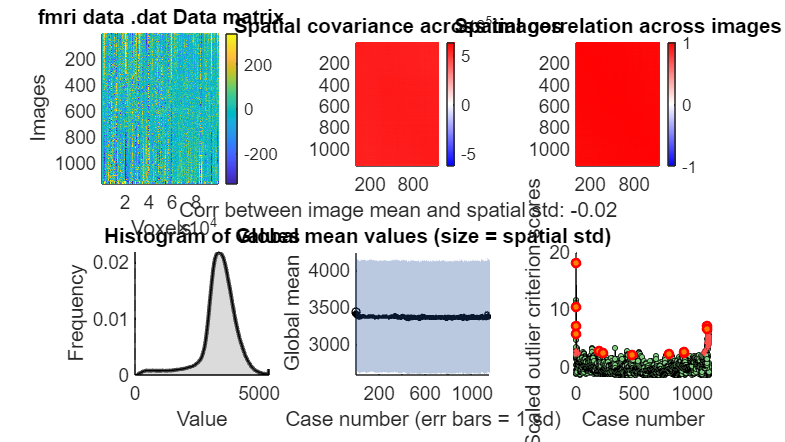

Grouping contiguous voxels:   1 regions
Grouping contiguous voxels:   1 regions
Grouping contiguous voxels:   1 regions


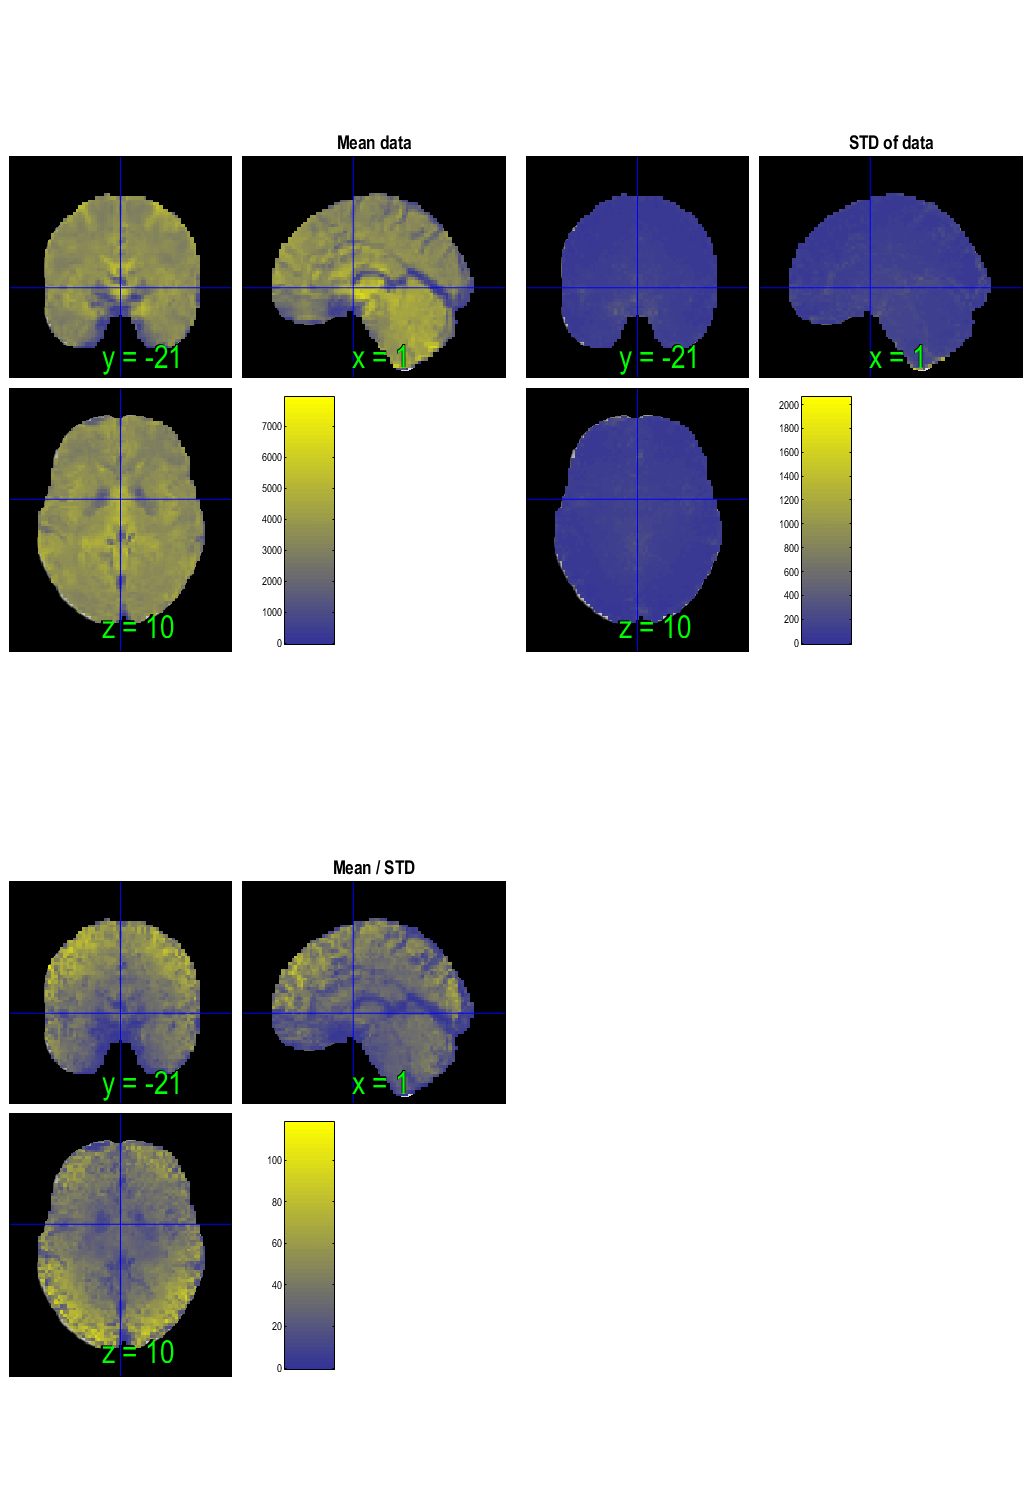

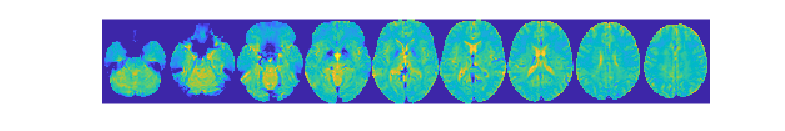

plot(f);

drawnow, snapnow

% Remove the task effects from each voxel
% resid_data = f.dat' - X.X(:, 1:end-1) * PX(1:end-1, :) * f.dat';
% 
% % Add the data back into the object
% f.dat = resid_data';
% 
% wh_outliers = plot(f);
% drawnow, snapnow

## **Preprocess the dataset**

We notice some slow drift, and some potential outliers Run **canlab_connectivity_preproc**, which runs a series of preprocessing steps: Steps in order [with defaults]: 

1. Remove nuisance covariates (and linear trend if requested) 

2. Remove ventricle and white matter - default: uses canonical images with eroded MNI-space masks for these tissue compartments 

3. High/low/bandpass filter on both data and covs before regression (plot) 

4. Residualization using regression (plot) 

5. (optional) Run additional GLM using the same additional preprocessing 

6. Windsorize based on distribution of full data matrix (plot) 

7. Extract region-by-region average ROI or pattern expression data

Canlab_connectivity_preproc: starting preprocessing ... 
::: removing ventricle & white matter signal ... 
Extracting from gray_matter_mask.nii.
Removing 196 voxels with one or more NaNs
Extracting from canonical_white_matter_thrp5_ero1.nii.
Extracting from canonical_ventricles_thrp5_ero1.nii.
Removing   9 voxels with one or more NaNs
::: temporal filtering brain data... 
::: temporal filtering covariates ... 
Windsorized data matrix to 3 STD; adjusted 1298038 values, 1.1% of values


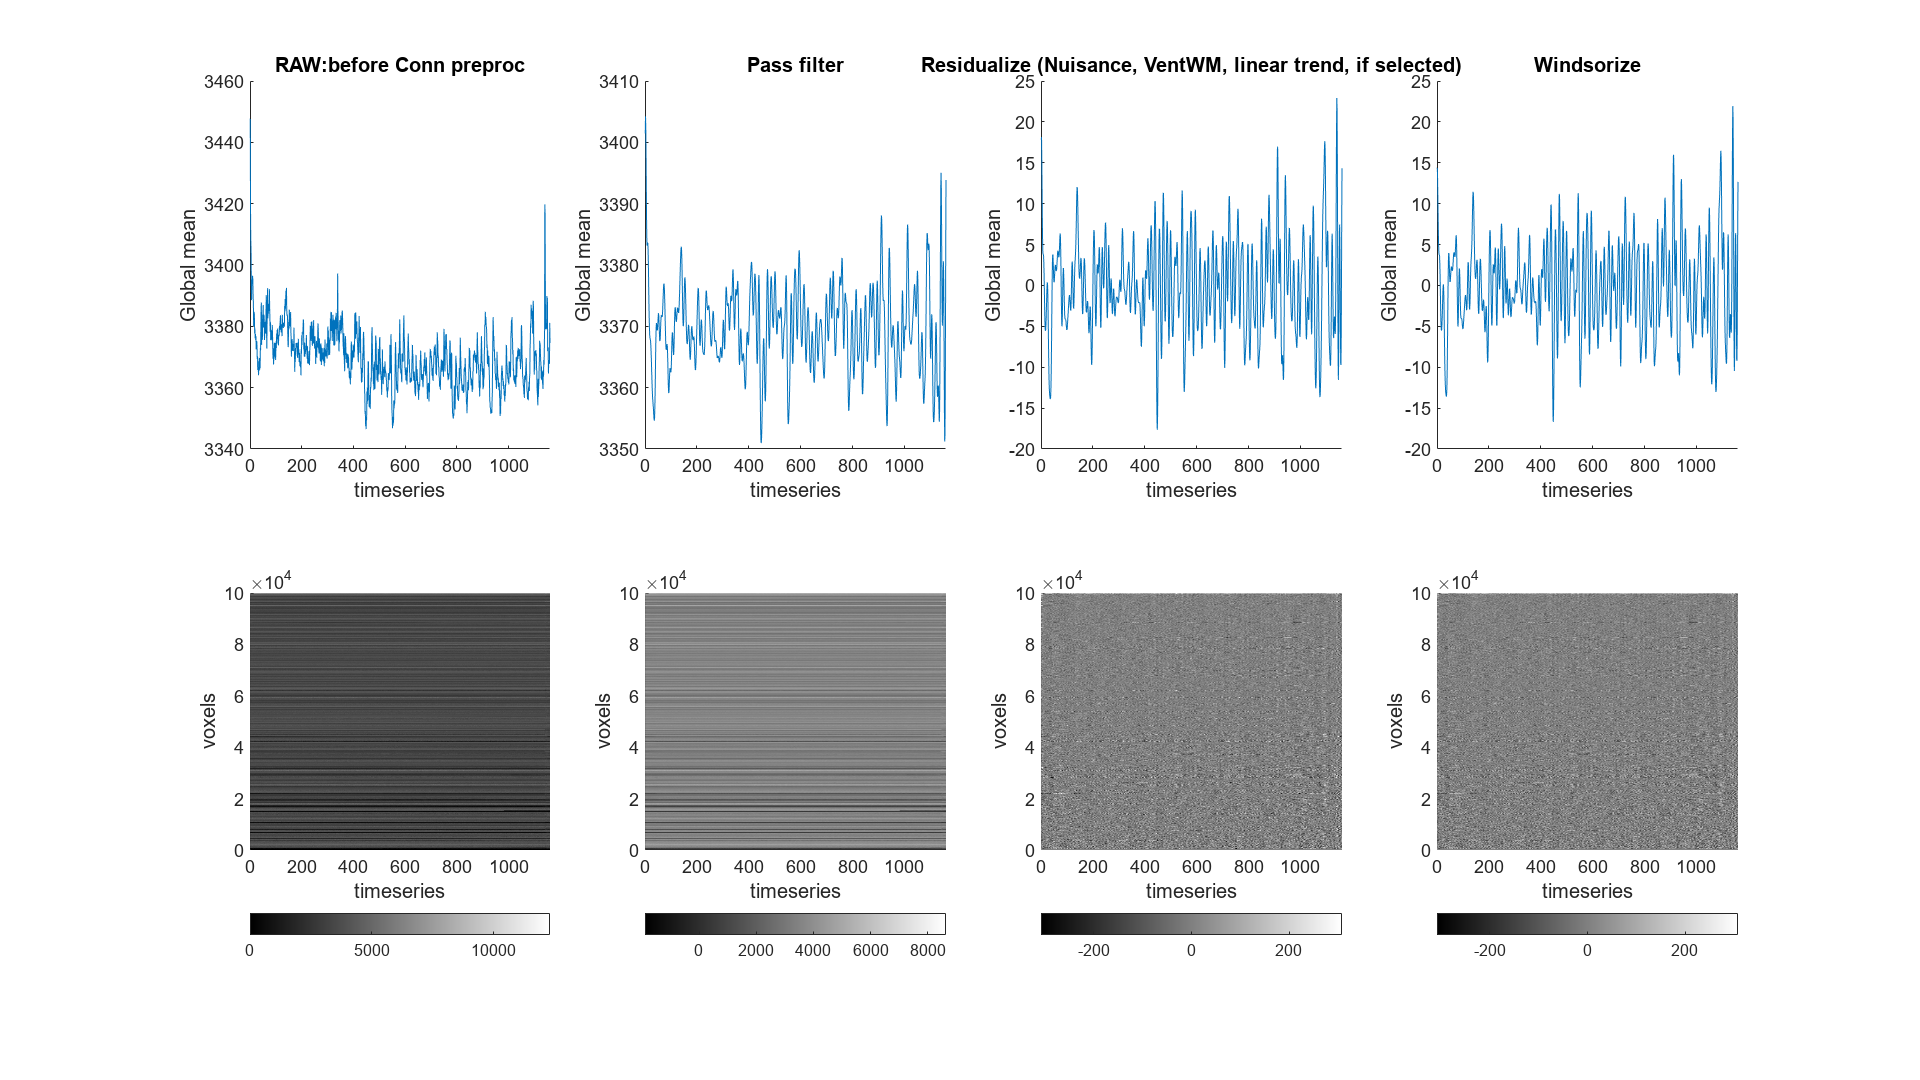

Done: data preprocessing in 6.0e+01 sec.

---------------------------------------------------------------



TR = 0.46;  % Repetition time between images
[preprocessed_dat] = canlab_connectivity_preproc(f, 'vw', 'windsorize', 3, 'bpf', [.008 .25], TR);

drawnow, snapnow

## Extract and plot left vs. right OP1 (S2) time series

atlas_obj=load_atlas('canlab2018_2mm');

Loading atlas: CANlab_combined_atlas_object_2018_2mm.mat


% Create a sub-atlas of regions whose labels match 'Ctx_1_'
op1_bilat = select_atlas_subset(atlas_obj, {'Ctx_OP1_'});

op1_bilat.labels;
% Extract the timeseries in the 'seed' region for this dataset
op1_bilat_timeseries = extract_data(op1_bilat, preprocessed_dat);

Resampling data object to space defined by atlas object.


## Plot the time series

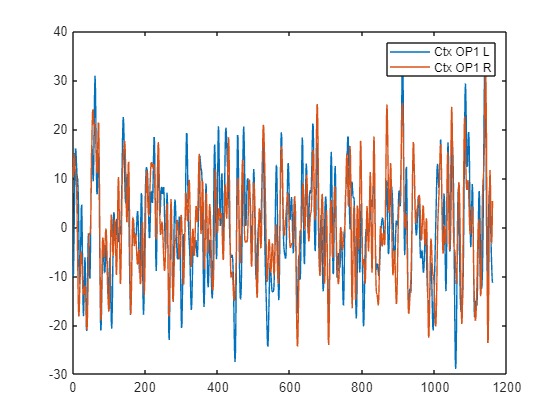

figure; plot(op1_bilat_timeseries)
legend(format_strings_for_legend(op1_bilat.labels))

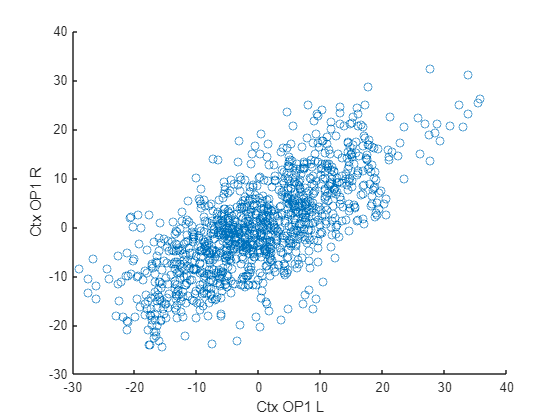

figure; scatter(op1_bilat_timeseries(:, 1), (op1_bilat_timeseries(:, 2)));
xlabel(format_strings_for_legend(op1_bilat.labels{1}))
ylabel(format_strings_for_legend(op1_bilat.labels{2}))

## Do a simple seed-based connectivity

op1_r = select_atlas_subset(atlas_obj, {'Ctx_OP1_R'});

% Extract the timeseries in the 'seed' region for this dataset
op1_r_timeseries = extract_data(op1_r, preprocessed_dat);

Resampling data object to space defined by atlas object.


% Assign seed region to .X field (design matrix) in data object, and run
% regression of this time series on all voxels
preprocessed_dat.X = op1_r_timeseries;

out = regress(preprocessed_dat);

Analysis: 
----------------------------------
Design matrix warnings:
----------------------------------
No intercept detected, adding intercept to last column of design matrix                                                     
Warning!!!  Some observations have high leverage values relative to others, regression may be unstable. abs(z(leverage)) > 3
Warning!!!  Too few variable names entered, less than size(X, 2). Names may be inaccurate.                                  
 
______________________________________________________
Running regression: 99837 voxels. Design: 1160 obs,   2 regressors, intercept is last

Predicting exogenous variable(s) in dat.X using brain data as predictors, mass univariate
Running in OLS Mode
Model run in 0 minutes and 0.97 seconds

Creating beta and t images, thresholding t images
__________________________________________________

% Regression method for fmri_data object
%
% Regress dat.X on dat.dat at each voxel, and return voxel-wise statistic
% images. Each column of dat.X is a predictor in a multiple regression,
% and the intercept is automatically added as the last column.

drawnow, snapnow

% The t-map for M1 connectivity is stored in the out.t, which has multiple
% images (one for the seed, and one for the intercept). We'll save the
% first one:

op1r_t_map = get_wh_image(out.t, 1);

% now we can re-threshold it however we want:

op1r_t_map = threshold(op1r_t_map, .001, 'unc');


Image   1
 88 contig. clusters, sizes   1 to 43986
Positive effect: 39477 voxels, min p-value: 0.00000000
Negative effect: 4622 voxels, min p-value: 0.00000000


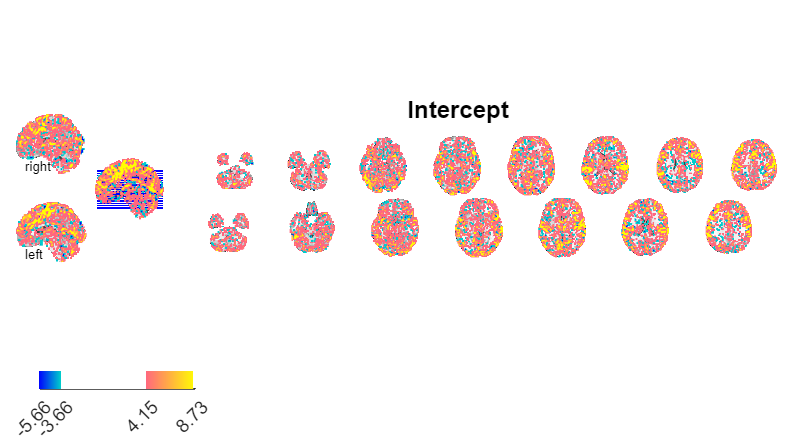

Setting up fmridisplay objects
Compressed NIfTI files are not supported.
sagittal montage: 1151 voxels displayed, 42948 not displayed on these slices
sagittal montage: 1138 voxels displayed, 42961 not displayed on these slices
sagittal montage: 1337 voxels displayed, 42762 not displayed on these slices
axial montage: 7929 voxels displayed, 36170 not displayed on these slices
axial montage: 8550 voxels displayed, 35549 not displayed on these slices


ans =   fmridisplay with properties:

            overlay: 'C:\Users\Admin\Documents\GitHub\canlab\CanlabCore\CanlabCore\canlab_canonical_brains\Canonical_brains_surfaces\fmriprep20_template.nii.gz'
              SPACE: [1×1 struct]
    activation_maps: {[1×1 struct]}
            montage: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
            surface: {}
          orthviews: {}
            history: {}
    history_descrip: []
    additional_info: ''

% display the map
create_figure('slices'); axis off
montage(op1r_t_map)

drawnow, snapnow

## Create a brainpathway object

Now we will use another object class, a "**brainpathway**" object This object class has specialized tools for handling connectivity and graphs.

% Show some of the methods (ignore 'static methods')
methods(brainpathway)

Loading atlas: CANlab_combined_atlas_object_2018_2mm.mat
Initializing nodes to match regions.

Methods for class brainpathway:

attach_voxel_data                      brainpathway                           brainpathway2fmri_data                 cluster_region_subset_by_connectivity  cluster_regions                        cluster_voxels                         copy                                   degree_calc                            find_node_indices                      nan2zero                               plot_connectivity                      reorder_regions_by_node_cluster        seed_connectivity                      select_atlas_subset                    threshold_connectivity                 

Static methods:

intialize_nodes                        update_node_connectivity               update_node_data                       update_region_connectivity             update_region_data                     

Methods of brainpathway inherited 

This is a special type of object: When you operate on the object ("b" below), it changes the values everywhere, automatically. So you don't have to pass the object (b) in or out of functions. If you want to create a copy of the object, use the copy() method, e.g., b_copy = copy(b)

% Create the object using your atlas
 b = brainpathway(atlas_obj);      % Construct a brainpathway object from an atlas object, here "pain_pathways"

Initializing nodes to match regions.



% b.region_atlas stores the atlas object within the brainpathways object you can assign a new atlas to change it.
% b.region_atlas.labels has all the labels for the regions.

b.region_atlas.labels(1:5)

ans = 1×5 cell array
    {'Ctx_V1_L'}    {'Ctx_V1_R'}    {'Ctx_MST_L'}    {'Ctx_MST_R'}    {'Ctx_V6_L'}

## Assign the subject's data to the object and calculate connectivity

When we do assign voxel-wise data to the object, it will automatically extract region averages for each parcel in the atlas and automatically calculate connectivity values

% First sample data to the space of the atlas
preprocessed_dat = resample_space(preprocessed_dat, atlas_obj);

% Now attach it to the brainpathway object (b) and calculate connectivity
b.voxel_dat = preprocessed_dat.dat;  % This calculates connectivity matrix and more when data are assigned

Updating node response data.
Updating obj.connectivity.nodes.
Updating obj.connectivity.nodes.
Updating region averages.
Updating obj.connectivity.regions.
Updating obj.connectivity.regions.


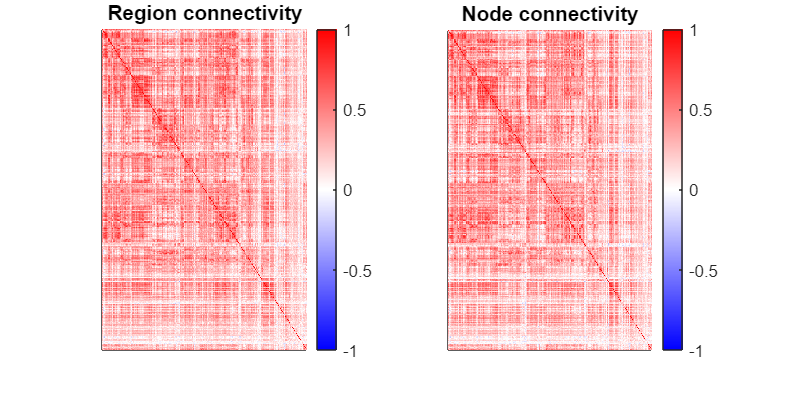

ans = struct with fields:
            r: [489×489 double]
            p: [489×489 double]
          sig: [489×489 logical]
    var_names: {}


% Now we have:
% b.connectivity.regions.r  : Correlation matrices for all pairs of regions
% b.connectivity.regions.p  : P-values for correlations (assuming independent noise)

% And we can visualize this:
plot_connectivity(b)

drawnow, snapnow

## Do a seed connectivity analysis

...with one or more seeds, specified by the atlas labels

% Calculate correlation maps with all network averages in right S2
fmri_dat_connectivity_maps = seed_connectivity(b, {'Ctx_OP1_R'});

Calculating correlations between region averages and seed regions.
Number of unique values in dataset: 490  Bit rate: 8.94 bits


% Calculate correlation maps with all network averages containing 'NAC' in the label
fmri_dat_connectivity_maps = seed_connectivity(b, {'NAC'});

Calculating correlations between region averages and seed regions.
Number of unique values in dataset: 978  Bit rate: 9.93 bits


Compressed NIfTI files are not supported.
Compressed NIfTI files are not supported.

SPM12: spm_check_registration (v7759)              23:16:56 - 22/11/2023
Display C:\Users\Admin\Documents\GitHub\canlab\CanlabCore\CanlabCore\canlab_canonical_brains\Canonical_brains_surfaces\fmriprep20_template.nii.gz,1
 (all)  

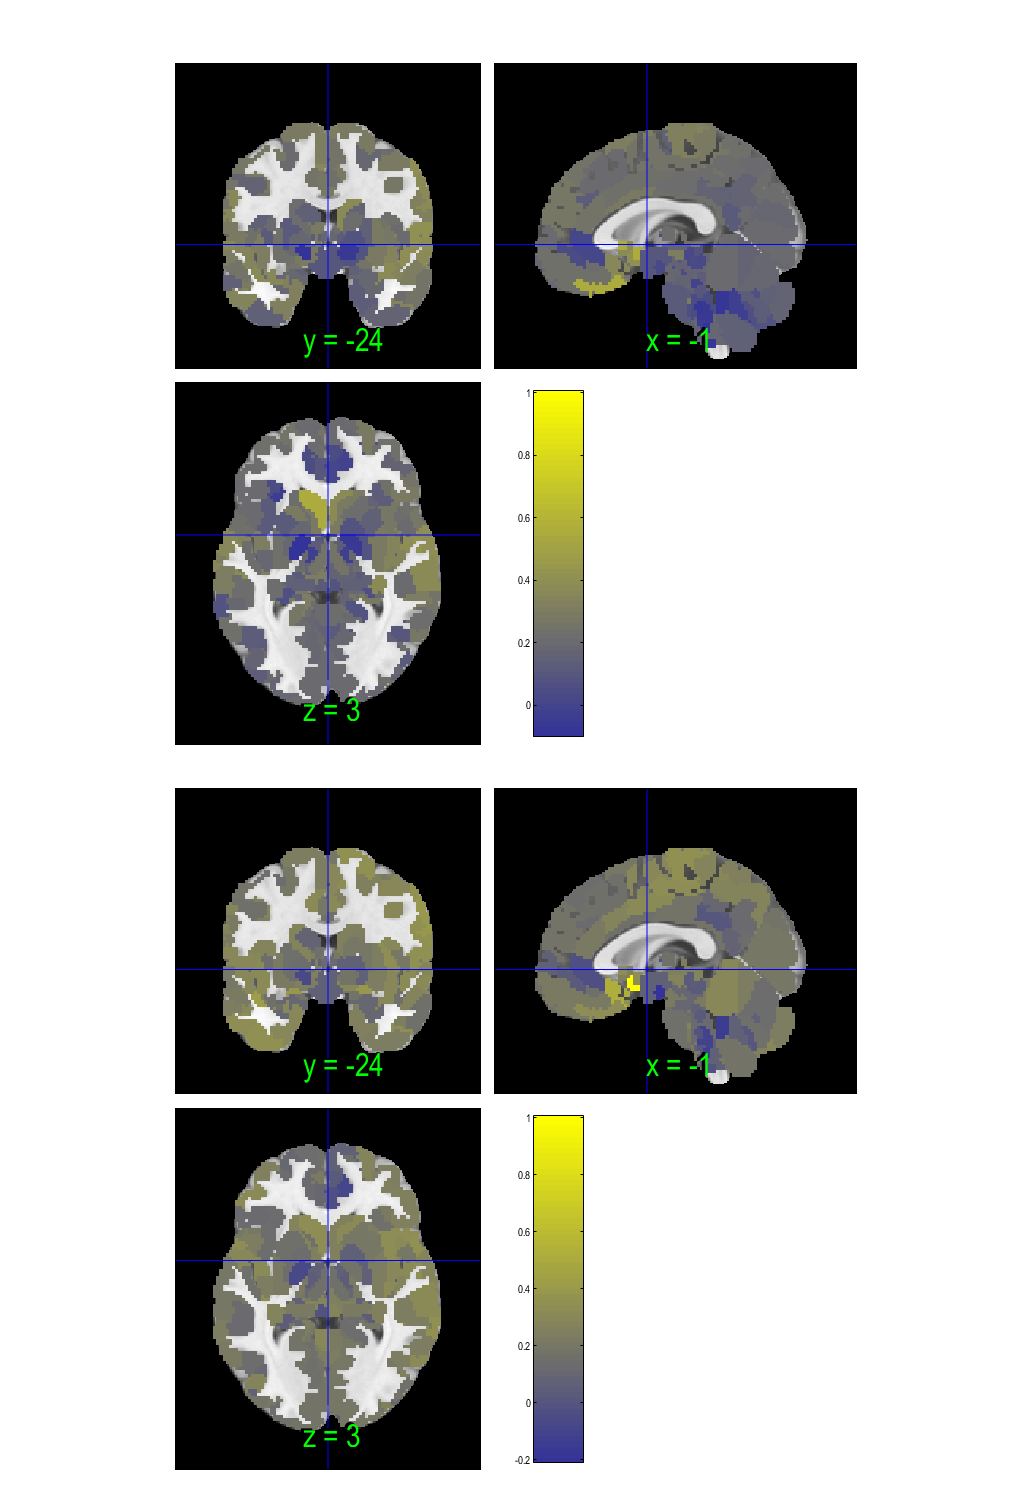

% Visualize the resulting maps, one per seed
orthviews(fmri_dat_connectivity_maps);

Setting up fmridisplay objects
Compressed NIfTI files are not supported.
sagittal montage: 6706 voxels displayed, 165005 not displayed on these slices
axial montage: 33691 voxels displayed, 138020 not displayed on these slices
sagittal montage: 6706 voxels displayed, 165005 not displayed on these slices
axial montage: 33691 voxels displayed, 138020 not displayed on these slices


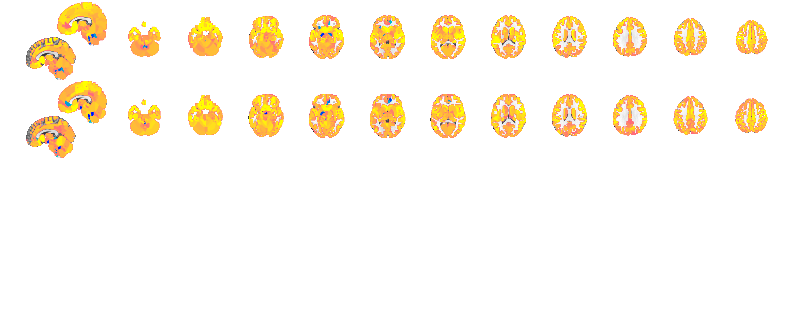

ans =   fmridisplay with properties:

            overlay: 'C:\Users\Admin\Documents\GitHub\canlab\CanlabCore\CanlabCore\canlab_canonical_brains\Canonical_brains_surfaces\fmriprep20_template.nii.gz'
              SPACE: [1×1 struct]
    activation_maps: {[1×1 struct]  [1×1 struct]}
            montage: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
            surface: {}
          orthviews: {}
            history: {}
    history_descrip: []
    additional_info: ''

montage(fmri_dat_connectivity_maps)